**John D'Uva**

**1/5/2021**

**Data Cleaning Exercise **

**Millenium Management**

**Step 1) Review the quality of the data, list any potential errors, and propose corrected values. Please list each quality check error and correction applied.**

Let's start by finding any datapoints in the various columns that look suspicious, such as outliers. We'll start with signal values:

signalOutlierIDXS = find(isoutlier(SampleDataset(:,2), 'movmedian', 120))

signalOutlierIDXS =          162
         260
         336
         501
         732
        1033
        1034
        1035
        1036
        1037


There are a number of outliers in the signal column which are potentially indicitive of issues with their prediction system. One problem that stands out is that the signal from `t=1033` through `t=1038` is all zeros while all other columns have values. We can't correct these zeros on our own because we don't have access to the signal prediction software – and it wouldn't make sense for us to fill in their predictions since our objective is to evaluate the quality of their predictions. For the sake of this assignment, one might consider a linear extrapolation from a window of prior values but such a calculation would give you unrealistic results since it wouldn't take into account the sinusoidal nature of stock prices:

window = 933:1032;
y = table2array(SampleDataset(window, 2));
signal_extrap = interp1(y, 101:107, 'linear', 'extrap')

signal_extrap =    18.6714   17.3262   15.9809   14.6357   13.2905   11.9452   10.6000


Within the signal data, there are also outliers at indices `[260, 336, 501, 732]` which could be accounted for by either (1) interpolating between prior values and posterior values, or (2) taking the average of the two adjacent signal values:

idx162 = (table2array(SampleDataset(161, 2))+table2array(SampleDataset(163, 2))) / 2

idx162 = 13.7547

idx260 = (table2array(SampleDataset(259, 2))+table2array(SampleDataset(261, 2))) / 2

idx260 = 15.3182

idx336 = (table2array(SampleDataset(335, 2))+table2array(SampleDataset(337, 2))) / 2

idx336 = 15.1678

idx501 = (table2array(SampleDataset(500, 2))+table2array(SampleDataset(502, 2))) / 2

idx501 = 17.5424

idx732 = (table2array(SampleDataset(731, 2))+table2array(SampleDataset(733, 2))) / 2

idx732 = 20.0436

The same process could be performed for outliers in the other data columns. Note: when we have consecutive rows of missing data, we cannot take a singular average so we must interpolate:

Open Data:

% Find the outlier indices
openOutlierIDXS = find(isoutlier(SampleDataset(:,3), 'movmedian', 120))

openOutlierIDXS =    779
   780
   781


% Solve for consecutive values
begin = table2array(SampleDataset(lowOutlierIDXS(1)-1, 3));
final = table2array(SampleDataset(lowOutlierIDXS(end)+1,3));
open_idx779 = linspace(begin, final, 5);
fprintf('openNewVals: %.3f\n', open_idx779(2:4) )

openNewVals: 132.405
openNewVals: 132.430
openNewVals: 132.455


High Data:

% Find the outlier indices
highOutlierIDXS  = find(isoutlier(SampleDataset(:,4), 'movmedian', 120))

highOutlierIDXS = 779

% Solve using average
highNewVals = (table2array(SampleDataset(778, 4))+table2array(SampleDataset(780, 4))) / 2

highNewVals = 132.5250

Low Data:

% Find the outlier indices
lowOutlierIDXS = find(isoutlier(SampleDataset(:,5), 'movmedian', 120))

lowOutlierIDXS =    779
   780
   781


% Solve for consecutive values
begin = table2array(SampleDataset(lowOutlierIDXS(1)-1,5));
final = table2array(SampleDataset(lowOutlierIDXS(end)+1,5));
low_idx779 = linspace(begin, final, 5);
fprintf('lowNewVals: %.3f\n', low_idx779(2:4) )

lowNewVals: 128.870
lowNewVals: 129.760
lowNewVals: 130.650


Close Data:

% Find the outlier indices
closeOutlierIDXS = find(isoutlier(SampleDataset(:,6), 'movmedian', 120))

closeOutlierIDXS =    586
   778
   779


% Generate solution (average)
closeIDX586 = (table2array(SampleDataset(585, 6))+table2array(SampleDataset(587, 6))) / 2

closeIDX586 = 157.0200

% Handle consecutive outliers
begin = table2array(SampleDataset(closeOutlierIDXS(2)-1,6));
final = table2array(SampleDataset(closeOutlierIDXS(3)+1,6));
low_idx779 = linspace(begin, final, 4);
fprintf('closeNewVals: %.3f\n', low_idx779(2:3) )

closeNewVals: 131.837
closeNewVals: 131.883


AdjClose Data:

adjcloseOutlierIDXS = find(isoutlier(SampleDataset(:,7), 'movmedian', 120))

adjcloseOutlierIDXS =    263
   339
   733
   779


% Generate solutions (average)
adjcloseIDX263 = (table2array(SampleDataset(262, 7))+table2array(SampleDataset(264, 7))) / 2

adjcloseIDX263 = 125.7913

adjcloseIDX339 = (table2array(SampleDataset(338, 7))+table2array(SampleDataset(340, 7))) / 2

adjcloseIDX339 = 128.9593

adjcloseIDX733 = (table2array(SampleDataset(732, 7))+table2array(SampleDataset(734, 7))) / 2

adjcloseIDX733 = 153.0754

adjcloseIDX779 = (table2array(SampleDataset(778, 7))+table2array(SampleDataset(780, 7))) / 2

adjcloseIDX779 = 127.0139

**2) Analyze the signal’s effectiveness or lack thereof in forecasting ETF price, using whatever metrics you think are most relevant.**

Let's visually compare the signal prediction data to the ground-truth data:

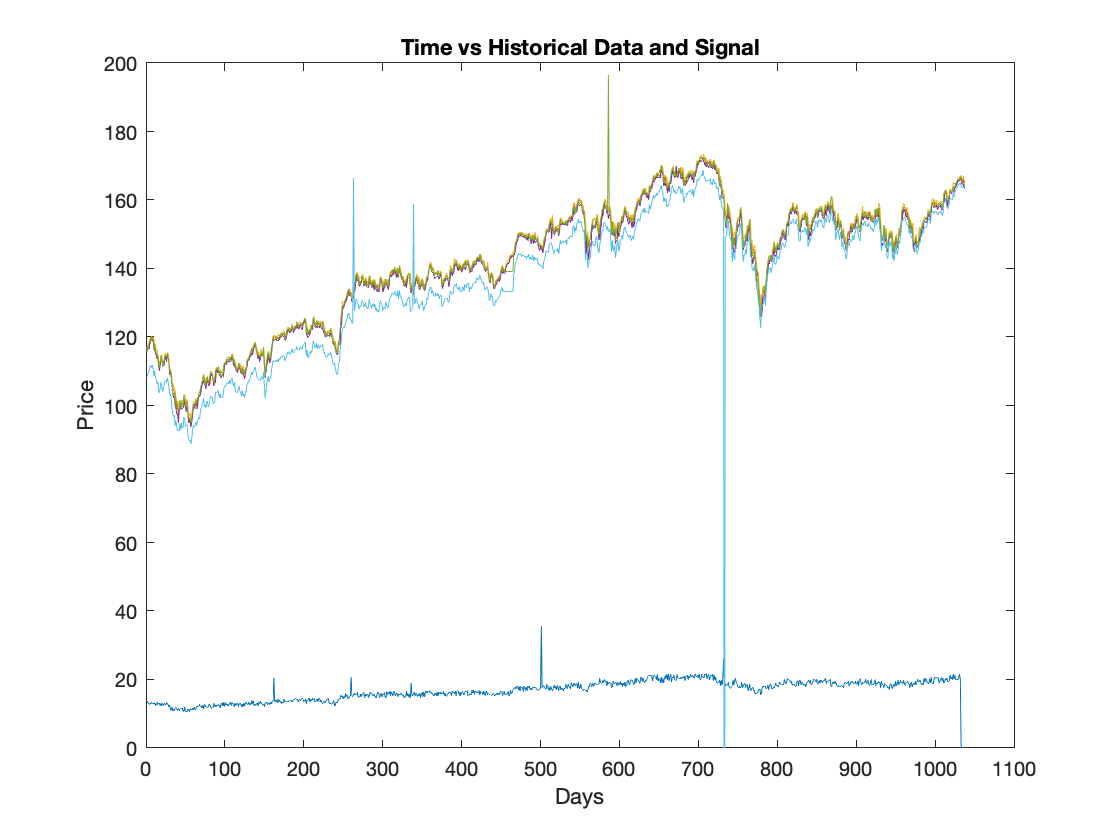

for i = 2: 7
    plot( table2array(SampleDataset(:,i)) ) 
    ylim([0, 200])
    xlim([0 1100])
    title('Time vs Historical Data and Signal')
    xlabel('Days')
    ylabel('Price')
    hold on
end

A few things stand out in this figure:

    1) Many of the outlier indices that we found in Step 1 have visibly erroneous values. This confirms our intuition that many of these values are likely errors that should be corrected. 

    2) The signal values are almost an order of magnitude away from the ground-truth values. The company's system likely has some kind of scaling issue, which we can temporarily account for by scaling the signal ourselves:

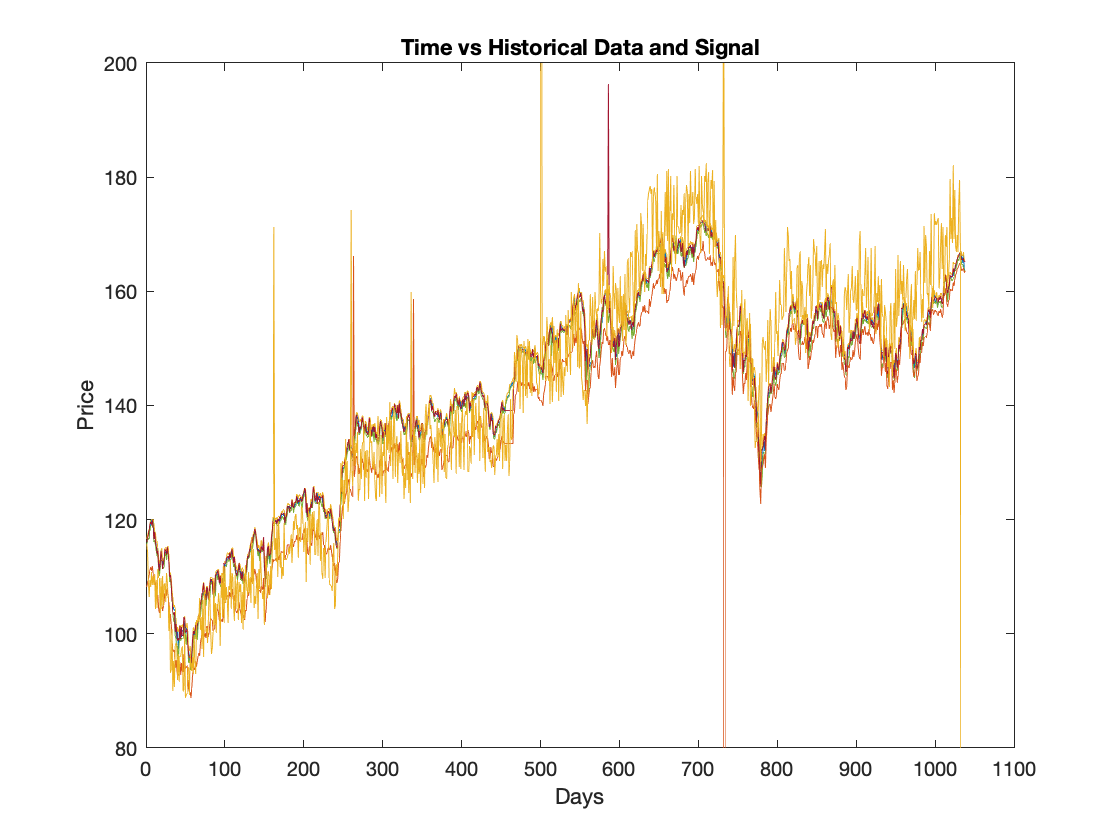

scaleFactor = 8.4;

cla()
for i = 3: 7
    plot( table2array(SampleDataset(:,i)) ) 
    plot( table2array(SampleDataset(:,2))*scaleFactor) 
    ylim([80, 200])
    xlim([0 1100])
    title('Time vs Historical Data and Signal')
    xlabel('Days')
    ylabel('Price')
    legend off
    hold on
end

Things seems to pass the "eye test" fairly well now that all of the datasets are scaled properly. We can get a measure of similarity between the historical data and the signal data by correlating the median of the various historical prices with the signal (mean is less appropriate here because of the outliers' presence):

signal = table2array(SampleDataset(:,2));
medianPrice = median(table2array(SampleDataset(:,3:7)),2);
r = corrcoef(signal, medianPrice) 

r =     1.0000    0.8029
    0.8029    1.0000


With a correlation of 80.29% between the signal and the historical price, we can safely say that the signal is significantly effective at forecasting ETF prices. If a system can predict the price of an ETF 80% of the time, it has the potential to be a valuable system. 

We can also use cross-correlation to measure the similarity between a vector and shifted (lagged) copies of a vector as a function of the lag. This let's us know how many x-units to shift the signal by in order to maximize correlation:

[r, lags] = xcorr(signal, medianPrice);
[~, IDX] = max(r);
lags(IDX)

ans = -6

This implies that we can get an even higher correlation between signal and median historical price if we shift the signal by six frames:

signal = [0;0;0;0;0;0; table2array(SampleDataset(:,2))];
medianPrice = [median(table2array(SampleDataset(:,3:7)),2); 0;0;0;0;0;0];
r = corrcoef(signal, medianPrice) 

r =     1.0000    0.9054
    0.9054    1.0000


We've now manipulated the signal values to have a correlation of 90% with the median historical price data. This has become a highly accurate system. Let's visualize the updated values to sanity check our work:

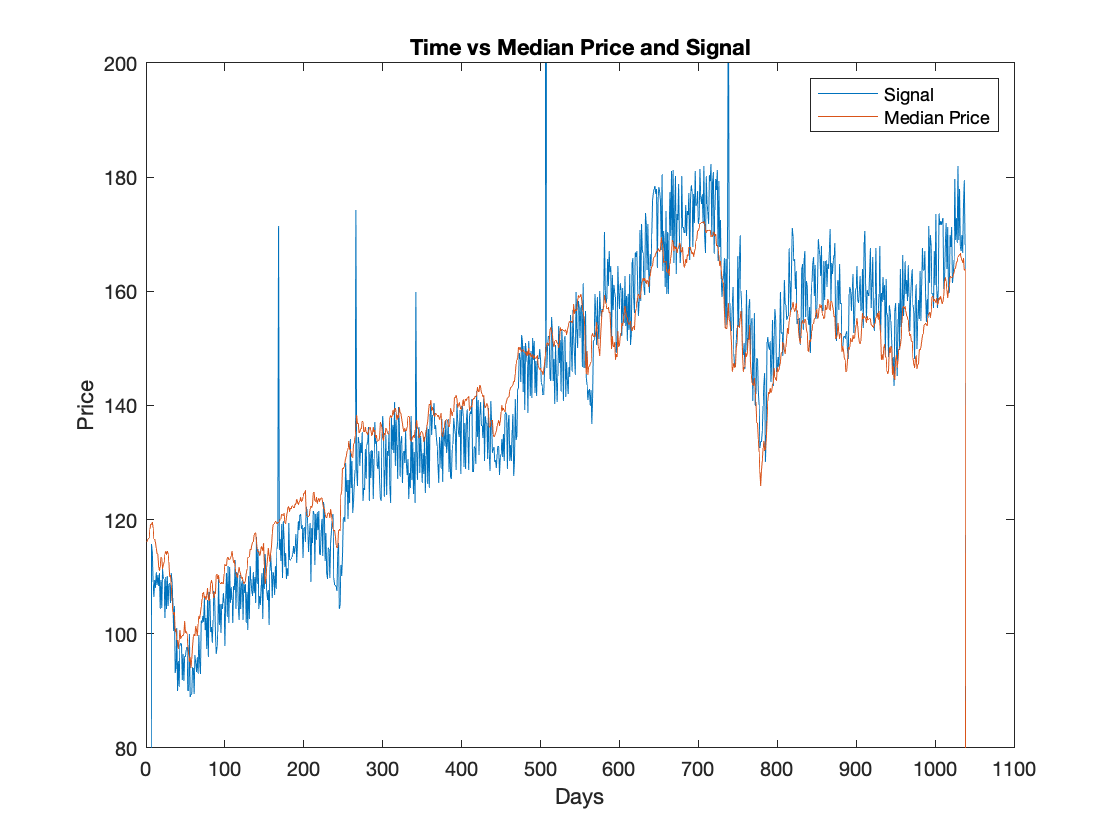

cla()
hold on
plot(signal*8.4)
plot(medianPrice)
title('Time vs Median Price and Signal')
xlabel('Days')
ylabel('Price')
legend('Signal', 'Median Price ')
hold off

**3)  Extra credit: Write a 1-2 paragraph summary for the Portfolio Manager addressing your observations about the efficacy and believability of the product, and recommendation for next steps.**

I believe that this is an effective system that deserves our attention. With some minor tweaking, the signal seems to believably predict the ETF price around 90% of the time. However, we should do more research before making a decision. I recommend that our next steps should be to further evaluate the system's performance using:

    1) data prior to 2015 (perhaps during 2008 financial crisis to determince how it handled adversity)

    2) data from other ETFs to determine how generalizable the system is within asset class

    3) data from other investment vehicles to determine how generalizable the system is across asset classes

It's worth noting that this sample datasent has come directly from the vendor (likely a sales rep) – meaning that they want us to see this particular data (and perhaps not others). We should keep in mind that this singular anecdote is not necessarily representivie of how the system would perform in general.

I would also have questions related to the artificial intelligence model that the firm is using. If they're implementing a neural network then I would want to know more about the model itself and what data it was trained on so that we can further determine its reliability. Knowing how a statistical system was built can tell you a lot about how it will perform – especially during edge cases like flash crashes, elections, etc. I might even look into the background of the firm and the engineers to find out how well-trained they are in this field. 

In summary, I believe that this system shows potential but more data is needed to confirm. I recommend moving forward with the above actions and making final decisions based on further research.